# Logit - Metropolis-Hastings algorithm

### Load data to use:

Apply the program to the Mroz dataset on female labor market participation (mroz.csv) 

% Specify the file path
filePath = "mroz.csv";

% Read the CSV file into a table
mrozTable = readtable(filePath);

% remove the missing value from the dataset
% mrozTable = rmmissing(mrozTable);

% Get the size of the dataset
datasetsize = size(mrozTable);

% Display the size of the dataset
disp(['Number of Rows: ', num2str(datasetsize(1))]);      % 753

Number of Rows: 753


disp(['Number of Columns: ', num2str(datasetsize(2))]);   % 22

Number of Columns: 22


### Generate the y and X for the Logit model:

For a logit model, we assume


$$y_i = \beta_0 + \beta_1 x_{1i} + \beta_2 x_{2i} + \cdots + \beta_p x_{pi} + u_i , \quad i = 1, \ldots, n$$


with $u_i \overset{iid}{\sim} \mathcal{N}(0, \sigma^2)$. In matrix form, this can be written as$y = X\beta + u$ where $y = (y_1, \ldots, y_n)$, $u = (u_1, \ldots, u_n)$ and 


$$X=\left\lbrack \begin{array}{ccccc}
1 & x_{11}  & x_{21}  & \cdots  & x_{\textrm{p1}} \\
1 & x_{12}  & x_{22}  & \cdots  & x_{\textrm{p2}} \\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
1 & x_{1n}  & x_{2n}  & \cdots  & x_{\textrm{pn}} 
\end{array}\right\rbrack$$


Then, we generate the dependent variable and independent variables X based on above form.

For the data, we will use:

    dependend varibale y: whether an individual was approved for a mortgage loan (approve)

    independent variable: 

- income aside from wage (nwifeinc)

- level of education (educ), 

- years of experience and its square (exper), 

- square of years of experience (exper2)

- age (age), 

- number of children less than 6 years of age (kidslt6),

- and number of children between 6 and 18 years of age (kidsge6)

We will have p = 7 and n equal to the the length of y vector.

% generate y
y_Data = mrozTable(:, 'inlf');
y = [table2array(y_Data)];

p = 7;
n = datasetsize(1);

% generate X
% n * (p+1)
X = [ones(n, 1), mrozTable.nwifeinc, mrozTable.educ, mrozTable.exper, mrozTable.exper.^2, mrozTable.age, mrozTable.kidslt6, mrozTable.kidsge6];       

### Set prior hyperparameters:

We can use the following noninformative prior values:


$$\underline{B} = 1000 \cdot I_{p+1}$$
          
$$\underline{\alpha} = 0.02$$
            

             
$$\underline{\beta} = 0_{p+1}$$
                    
$$\underline{\delta} = 0.02$$
				

where $I_{p+1}$ is an identity matrix of size (p + 1) × (p + 1) and $0_{p+1}$ is a vector of zeros of dimension p + 1. 

% other noninformative prior values
I = eye(p + 1);                     % identity matrix of size (p+1)*(p+1)
zeroVector = zeros(p + 1, 1);       % a vector of zeros of dimension p + 1

B_underbar = 1000 * I;              % B = 1000·Ip+1; (p+1)*(p+1)
beta_underbar = zeroVector;         % β = 0p+1; (p+1)*1

alpha_underbar = 0.02;              % α = 0.02    
delta_underbar = 0.02;              % δ = 0.02

### Set algorithm values

1. Specify the burn-in and main iteration periods

We use a burn-in period of 5,000 iterations and keep 10,000 final iterations to estimate posterior means (for a total of 15,000 iterations). 

% iterations to estimate posterior means
burn_in_iter = 5000;                % burn-in period of 5,000 iterations 
final_iter = 10000;                 % 10,000 final iterations
nsim = burn_in_iter + final_iter + 1;
keep = (burn_in_iter + 2):nsim; % Iterations to keep

2. Specify initial values

In our modal, we use a latent variable representation to formalize the model. Let $y^*$ be a latent unobserved variable that is related to the observed outcome y, where 


$$y_i^* = \beta_0 + \beta_1 x_{1i} + \beta_2 x_{2i} + \cdots + \beta_p x_{pi} + u_i = x^\top \beta + u_i, \quad i = 1, \ldots, n$$


Here, $\beta = (\beta_0, \beta_1, \ldots, \beta_p)$ is a p + 1 vector of coefficients and now $u_i$ is assumed to have a logistic distribution $P(U_i < u_i) = \frac{e^{u_i}}{1+e^{u_i}}$ with density $p(u_i) = \frac{e^{u_i}}{({1+e^{u_i}})^2}$.

The logistic distribution is of form:


$$p(y|\beta) = \prod_{i=1}^{n} [\frac{exp({x_i^{\top}{\beta})}} {1+exp(x_i^{\top}{\beta})}]^{y_i} [\frac{1} {1+exp(x_i^{\top}{\beta})}]^{1-y_i} $$


For Metropolis-Hastings algorithm, 

the posterior is

$p(\beta|y)\propto \prod_{i=1}^{n} [\frac{exp({x_i^{\top}{\beta})}} {1+exp(x_i^{\top}{\beta})}]^{y_i} [\frac{1} {1+exp(x_i^{\top}{\beta})}]^{1-y_i} \times \text{exp}[-\frac{1}{2}(\beta-\underline{\beta})^{\top}\underline{B}^{-1}(\beta-\underline{\beta})]$,

and the proposal is $g(\beta) = \text{N}_{p+1}(\beta|\hat{\beta},\Omega)$, which is	a multivariate normal distribution with mean given by the maximum likelihood estimate $\hat{\beta}$ and variance-covariance matrix $\Omega = \tau^2(\hat{\Sigma}^{-1}+\underline{B}^{-1})^{-1}$ where $\tau$ is a tuning parameter and $\hat{\Sigma}$ is the maximum likelihood estimate of the variance given by the negative inverse of the log-likelihood Hessian at $\hat{\beta}$, i.e., 


$$\hat{\Sigma} = -[\text{H}(\hat{\beta})]^{-1} = -[\frac{\partial^2}{\partial\beta^2}\text{log}p(y|\beta)|_{\beta=\hat{\beta}}]^{-1}$$


See bouns point for the steps of getting Hessian: 

$H(\hat{\beta})=\frac{\partial(\text{log}^2(p(y|x)}{\partial{\beta}^2} |_{\beta=\hat{\beta}}= -\sum_{i=1}^{n} x_ix_i^{\top}(1-\frac{\text{exp}(x_i^{\top}\hat{\beta})}{1+\text{exp}(x_i^{\top}\hat{\beta}))})(\frac{\text{exp}(x_i^{\top}\hat{\beta}))}{1+\text{exp}(x_i^{\top}\hat{\beta}))}) = -X^{\top}WX$,

where $W = (1-\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})(\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})$, and X is the independent variable.

We can then compute $\hat{\Sigma} = -[H(\hat{\beta})]^{-1} $, and $\Omega = \tau^2(\hat{\Sigma}^{-1}+\underline{B}^{-1})^{-1}$.

By inverse rule, $\Omega = \tau^2(({-[-X^{\top}WX]^{-1} })^{-1}+\underline{B}^{-1})^{-1} = \tau^2((X^{\top}WX)+\underline{B}^{-1})^{-1}$  

We impose $\tau$ = 1.

We then need to get acceptance ratio for updating our algorithm.

The general fomula of the ratio is:

$\alpha(\theta^*,\theta^{s-1})=min\lbrace{\frac{ p(\theta^*|y)g_s(\theta^{(s-1)}|\theta^*)}{p(\theta^{s-1}|y)g_s(\theta^*|\theta^{(s-1)})},1\rbrace$.

We take the log on $\frac{ p(\theta^*|y)g_s(\theta^{(s-1)}|\theta^*)}{p(\theta^{s-1}|y)g_s(\theta^*|\theta^{(s-1)})}$  and create log functions to calculate the ratio step by step.

After the calculation, we take the exponential to compare with value 1 and get the result of $\alpha(\theta^*,\theta^{s-1})$.

tau = 1;          % Start with τ = 1, the tuning parameter for the proposal distribution

% Obtain maximum likelihood estimates beta_hat(using existing functions)
% beta_hat = inv(X' * X) * X'* y;
beta_hat = glmfit(X(:, 2:end), y, 'binomial', 'link', 'logit');

% the logistic distribution function
u = exp(X * beta_hat) ./ (1 + exp(X * beta_hat));

% Calculate weights
W = diag(u .* (1 - u));
    
% Calculate Hessian matrix
Hessian = - X' * W * X;

% Ω = τ^2 ( Σˆ − 1 + B − 1 ) − 1
% Σ_hat is the maximum likelihood estimate of the variance 
% given by the negative inverse of the log-likelihood Hessian at β_hat
omega = tau ^ 2 * inv(X' * W * X + inv(B_underbar));


% Initialize variables
beta_MH = zeros(nsim, p + 1);
beta_MH(1,:) = beta_hat;

% Metropolis-Hastings algorithm
for iter = 2 : nsim
    % Propose a new beta using a multivariate normal distribution
    beta_proposed = mvnrnd(beta_MH(iter - 1,:), omega);

    log_ratio = ratio(beta_proposed', beta_MH(iter - 1,:)', X, y, B_underbar, omega);

    acc_Ratio = min(1,exp(log_ratio));
    
    % Accept or reject the proposal
    if rand() < acc_Ratio
        beta_MH(iter, :) = beta_proposed;
    else
        beta_MH(iter, :) = beta_hat;
    end
    
end

% Display the posterior samples for beta
%disp('Posterior Samples for Beta:');
%disp(beta_MH);

### Summary of posteriors:

We should drop the value for the burn-in iterations and only keep the value for the last 10000 iterations.

% Remove the Burn-in iterations and only keeop the final iteration betas
% Store samples after burn-in iterations
beta_final = beta_MH(keep, :);

% estimate
beta_means = mean(beta_final)';
beta_medians = median(beta_final)';
beta_sds = std(beta_final)';

%print
beta = [beta_means, beta_medians]';
row = {'mean', 'median'};
array2table(beta, 'RowNames', row)

ans = 2×8 table
               beta1       beta2       beta3      beta4       beta5         beta6       beta7      beta8  
              _______    _________    _______    _______    __________    _________    _______    ________

    mean      0.71421    -0.021768    0.22039    0.20589    -0.0031391    -0.093414    -1.5479    0.048173
    median    0.42545    -0.021345    0.22117    0.20587    -0.0031541    -0.088024    -1.4434    0.060112


 Let's also get the trace plots, density plots and autocorrelation plots.

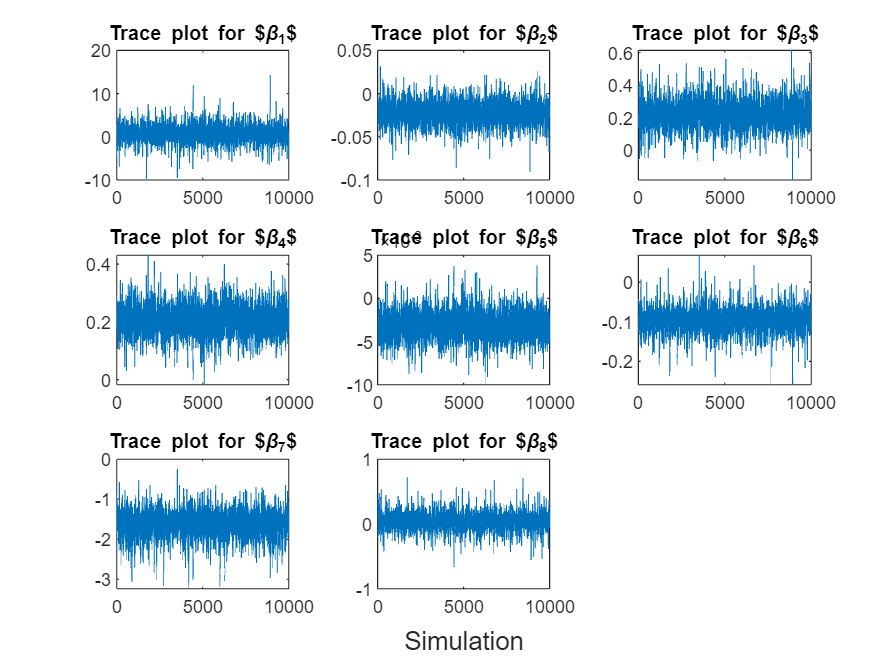

% Trace plots
figure
t = tiledlayout(3, 3);
for j = 1:p+1
    nexttile
    plot(beta_final(:, j))
    hold on
    title("Trace plot for $\beta_{" + j + "}$")
    hold off
end
xlabel(t, "Simulation")

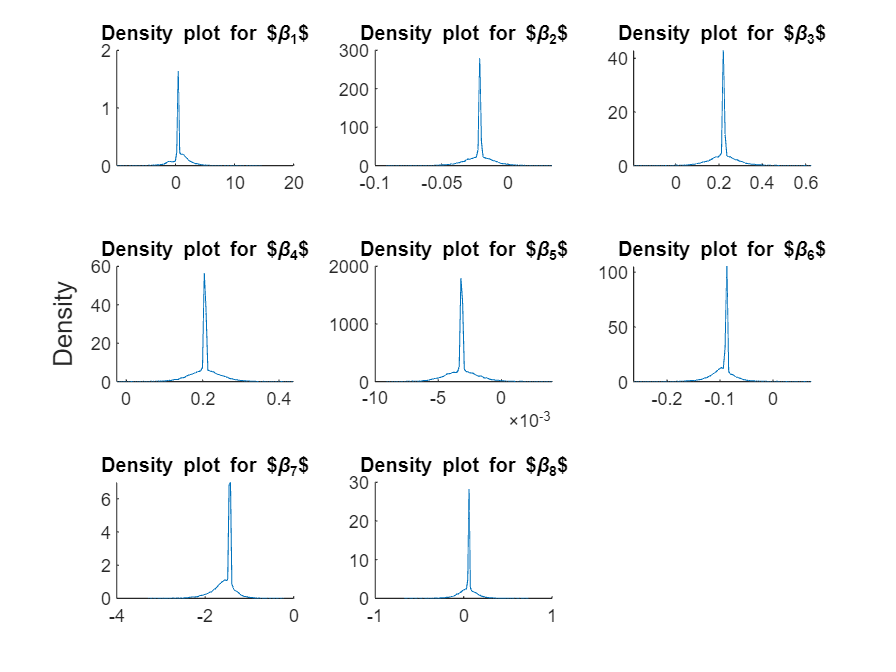


% Density plots
figure
t = tiledlayout(3, 3);
for j = 1:p+1
    nexttile
    hold on
    ksdensity(beta_final(:, j))
    hold off
    title("Density plot for $\beta_{" + j + "}$")
end
ylabel(t, "Density")

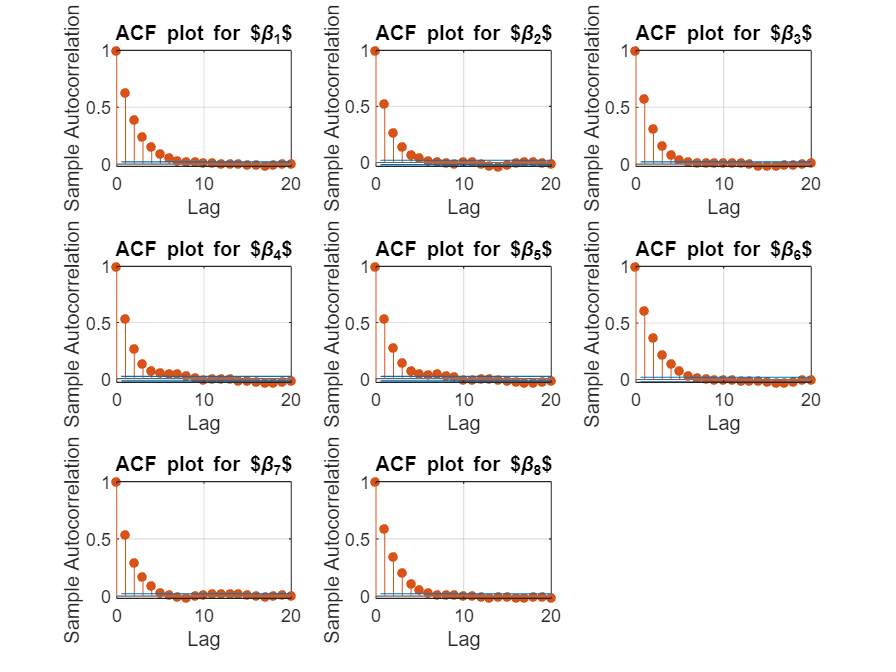

% Autocorrelation plots
figure
tiledlayout(3, 3);
for j = 1:p+1
    nexttile
    autocorr(beta_final(:, j))
    title("ACF plot for $\beta_{" + j + "}$")
end

### Marginal Effects:

To have a better understanding of the effect of each $\beta_i$ on the outcome $y$ in the Trobit model, we need to take the marginal effects on our $\beta_i$.

% beta_MH is our matrix of posterior draws
% Each row in beta_MH is a draw from the posterior distribution
% Columns represent different coefficients

% X is our data matrix (excluding the dependent variable)
% Initialize matrix to store predicted probabilities
predicted_probs = zeros(size(X,1), size(beta_MH,1));

for i = 1:size(beta_MH,1)
    predicted_probs(:,i) = normcdf(X * beta_MH(i,:)');
end

% Initialize matrix to store marginal effects
marginal_effects = zeros(size(X,2), size(beta_MH,1));

for i = 1:size(beta_MH,1)
    % Calculate the linear predictor for this draw
    z = X * beta_MH(i,:)';
    % Calculate the PDF of the normal distribution at these values
    pdf_values = normpdf(z);
    % Calculate marginal effects for each variable
    for j = 1:size(X,2)
        marginal_effects(j,i) = mean(pdf_values .* X(:,j) * beta_MH(i,j));
    end
end

% Average the marginal effects across all draws
average_marginal_effects = mean(marginal_effects,2);
%print
marginal_beta = (average_marginal_effects)';
row = {'average_marginal_beta_effect'};
array2table(marginal_beta, 'RowNames', row)

ans = 1×8 table
                                    marginal_beta1    marginal_beta2    marginal_beta3    marginal_beta4    marginal_beta5    marginal_beta6    marginal_beta7    marginal_beta8
                                    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________

    average_marginal_beta_effect       0.15087          -0.096355          0.57899           0.42438          -0.097943          -0.86115         -0.078448          0.014382   


Bonus point:

The logistic regression likelihood function: 


$$p(y|x) = \prod_{i=1}^{n} [\frac{exp({x_i^{\top}{\beta})}} {1+exp(x_i^{\top}{\beta})}]^{y_i} [\frac{1} {1+exp(x_i^{\top}{\beta})}]^{1-y_i}$$


The log-likelihood function is the natural logarithm of the likelihood function: 


$$\text{log} p(y|x) = \sum_{i=1}^{n} [y_i \text{log}(\frac{exp({x_i^{\top}{\beta})}}{1+exp(x_i^{\top}{\beta})})+(1-y_i)log(\frac{1} {1+exp(x_i^{\top}{\beta})})] $$


                                                                    
$$= \sum_{i=1}^{n} [ y_i x_i^{\top} \beta-y_i\text{log}(1+exp(x_i^{\top}{\beta})) + (1-y_i)\text{log}(1) - (1-y_i)\text{log}(1+exp(x_i^{\top}{\beta})) ]$$
	

                                                                    
$$= \sum_{i=1}^{n} [ y_i x_i^{\top} \beta-\text{log}(1+exp(x_i^{\top}{\beta})) ]$$
				

The first partial derivatives of the log-likelihood with respect to the elements of β: 


$$\frac{\partial(\text{log}(p(y|x)}{\partial{\beta}} = \sum_{i=1}^{n}(y_i-\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})x_i$$


The Hessian matrix, denoted as H, is the matrix of the second partial derivatives of the log-likelihood with respect to the elements of β. 


$$H(\beta)=\frac{\partial(\text{log}^2(p(y|x)}{\partial{\beta}^2} = -\sum_{i=1}^{n} x_ix_i^{\top}(1-\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})(\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})$$


For a simplier notation:

$H(\beta)=\frac{\partial(\text{log}^2(p(y|x)}{\partial{\beta}^2} = -X^{\top}WX$,

where $W = (1-\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})(\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})$, and X is the independent variable.